clc;
clear;
close all;

%% PARAMETERS
num_nodes = 6;          % number of nodes in ring
sim_time = 5;           % seconds
dt = 0.001;
time = 0:dt:sim_time;

lambda = 25;            % packet generation rate per node
packet_size = 1000;     % bits
data_rate = 1e6;       % 1 Mbps

token_time = 0.002;    % token holding time per node

%% INITIALIZATION
queues = zeros(1, num_nodes);   % packet queue at each node
current_node = 1;

total_generated = 0;
total_sent = 0;
delay = [];

token_circulations = 0;

%% SIMULATION LOOP
for t = 1:length(time)
    
    %% PACKET GENERATION
    for i = 1:num_nodes
        if rand < lambda*dt
            queues(i) = queues(i) + 1;
            total_generated = total_generated + 1;
        end
    end
    
    %% TOKEN PROCESSING
    if queues(current_node) > 0
        
        % transmit one packet
        tx_time = packet_size / data_rate;
        
        queues(current_node) = queues(current_node) - 1;
        total_sent = total_sent + 1;
        
        delay = [delay tx_time];
    end
    
    %% MOVE TOKEN TO NEXT NODE
    if mod(t, round(token_time/dt)) == 0
        current_node = current_node + 1;
        
        if current_node > num_nodes
            current_node = 1;
            token_circulations = token_circulations + 1;
        end
    end
end

%% PERFORMANCE METRICS

throughput = (total_sent * packet_size) / sim_time;

if total_generated > 0
    utilization = (total_sent / total_generated) * 100;
    packet_loss = ((total_generated - total_sent) / total_generated) * 100;
else
    utilization = 0;
    packet_loss = 0;
end

if ~isempty(delay)
    avg_delay = mean(delay) * 1000;
else
    avg_delay = 0;
end

%% RESULTS
fprintf('--- TOKEN RING PERFORMANCE ---\n');

--- TOKEN RING PERFORMANCE ---


fprintf('Total Generated Packets = %d\n', total_generated);

Total Generated Packets = 727


fprintf('Total Sent Packets = %d\n', total_sent);

Total Sent Packets = 727


fprintf('Token Circulations = %d\n', token_circulations);

Token Circulations = 416


fprintf('Throughput = %.2f bps\n', throughput);

Throughput = 145400.00 bps


fprintf('Utilization = %.2f %%\n', utilization);

Utilization = 100.00 %


fprintf('Packet Loss = %.2f %%\n', packet_loss);

Packet Loss = 0.00 %


fprintf('Average Delay = %.4f ms\n', avg_delay);

Average Delay = 1.0000 ms


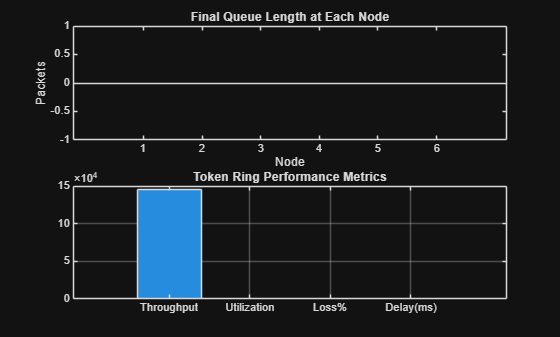


%% PLOTS

figure;

subplot(2,1,1);
bar(queues);
title('Final Queue Length at Each Node');
xlabel('Node');
ylabel('Packets');

subplot(2,1,2);
bar([throughput utilization packet_loss avg_delay]);
set(gca, 'XTickLabel', {'Throughput','Utilization','Loss%','Delay(ms)'});
title('Token Ring Performance Metrics');
grid on;